disp("=== Summary Statistics of Features ===");

=== Summary Statistics of Features ===


summary(SFeaturesByFault)

Variables:

    FaultType: 288×1 string

    Variable: 288×1 cell array of character vectors

    Mean: 288×1 double

        Values:

            Min       -400.25 
            Median     55.135 
            Max        402.79 

    Max: 288×1 double

        Values:

            Min       -400.25 
            Median     77.125 
            Max        410.57 

    RMS: 288×1 double

        Values:

            Min       0.18434 
            Median     55.608 
            Max        402.79 

    SRM: 288×1 double

        Values:

            Min       0.035312
            Median      55.184
            Max         402.79

    StdDev: 288×1 double

        Values:

            Min       3.6193e-14
            Median        1.6302
            Max           20.953

    Variance: 288×1 double

        Values:

            Min       1.31e-27
            Me

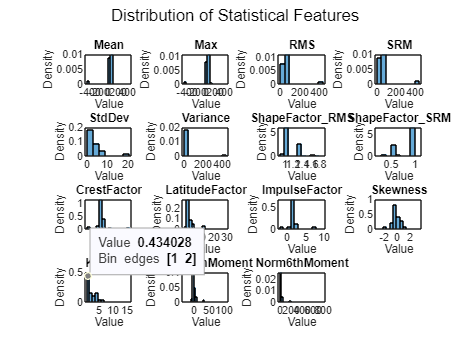

featureNames = SFeaturesByFault.Properties.VariableNames(3:end);  % skip 'FaultType' and 'Variable'

figure;
for i = 1:length(featureNames)
    subplot(4, 4, i);  % Adjust based on how many features (15 → 4x4)
    histogram(SFeaturesByFault.(featureNames{i}), 'Normalization', 'pdf');
    title(featureNames{i}, 'Interpreter', 'none');
    xlabel('Value');
    ylabel('Density');
end
sgtitle('Distribution of Statistical Features');

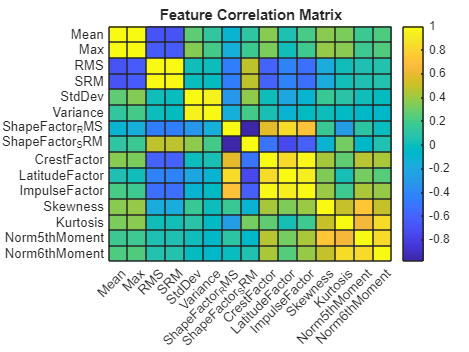

% Compute correlation matrix
featureData = table2array(SFeaturesByFault(:, 3:end));
corrMatrix = corrcoef(featureData, 'Rows', 'pairwise');

% Plot heatmap
figure;
heatmap(featureNames, featureNames, corrMatrix, ...
    'Colormap', parula, 'ColorbarVisible', 'on');
title('Feature Correlation Matrix');

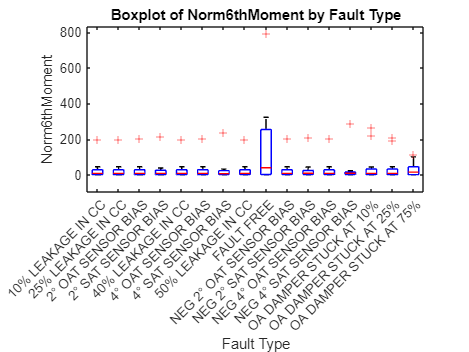

faultTypes = unique(SFeaturesByFault.FaultType);
featureToPlot = 'Norm6thMoment';  % You can loop over others if needed

figure;
boxplot(SFeaturesByFault.(featureToPlot), SFeaturesByFault.FaultType);
title("Boxplot of " + featureToPlot + " by Fault Type");
xlabel("Fault Type");
ylabel(featureToPlot);
xtickangle(45);